# Pick-and-Place Workflow using Stateflow for MATLAB

This example shows how to setup an end-to-end pick and place workflow for a robotic manipulator like the KINOVA® Gen3.

## Overview

This example sorts detected objects onto shelves using a KINOVA Gen3 manipulator. The example uses tools from four toolboxes:

- **Robotics System Toolbox™ **is used to model, simulate, and visualize the manipulator, and for collision-checking.

- **Model Predictive Control Toolbox™ **and** Optimization Toolbox™ **are used to generated optimized, collision-free trajectories for the manipulator to follow.

- **Stateflow® **is used to schedule the high-level tasks in the example and step from task to task.

This example builds on key concepts from two related examples:

- [Plan and Execute Task- and Joint-Space Trajectories Using a KINOVA Gen3 Manipulator](docid:robotics_examples.mw_20e8553c-fc75-4688-8696-bac1b2693fa8) shows how to generate and simulate interpolated joint trajectories to move from an initial to a desired end-effector pose. 

- [Plan and Execute Collision-Free Trajectories Using a KINOVA Gen3 Manipulator](docid:robotics_examples.mw_8454573b-3123-45c5-9ae1-6774f66b40a6) shows how to plan closed-loop collision-free robot trajectories to a desired end-effector pose using nonlinear model predictive control.

## Stateflow Chart

This example uses a Stateflow chart to schedule tasks in the example. Open the chart to examine the contents and follow state transitions during chart execution.

edit exampleHelperFlowChartPickPlace.sfx

The chart dictates how the manipulator interacts with the objects, or parts. It consists of basic initialization steps, followed by two main sections:

- Identify Parts and Determine Where to Place Them

- Execute Pick-and-Place Workflow

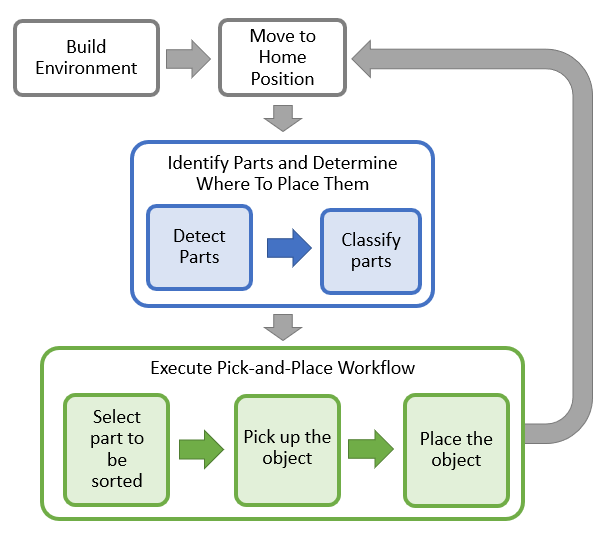

### Initialize the Robot and Environment

First, the chart creates an environment consisting of the Kinova Gen3 manipulator, three parts to be sorted, the shelves used for sorting, and a blue obstacle. Next, the robot moves to the home position.

### Identify the Parts and Determine Where to Place Them

In the first step of the identification phase, the parts must be detected. The exampleCommand`DetectParts` function directly gives the object poses. Replace this class with your own object detection algorithm based on your sensors or objects.

Next, the parts must be classified. The exampleCommand`ClassifyParts` function classifies the parts into two types to determine where to place them (top or bottom shelf). Again, you can replace this function with any method for classifying parts.

### Execute Pick-and-Place Workflow

Once parts are identified and their destinations have been assigned, the manipulator must iterate through the parts and move them onto the appropriate tables.

#### Pick up the Object

The picking phase moves the robot to the object, picks it up, and moves to a safe position, as shown in the following diagram:

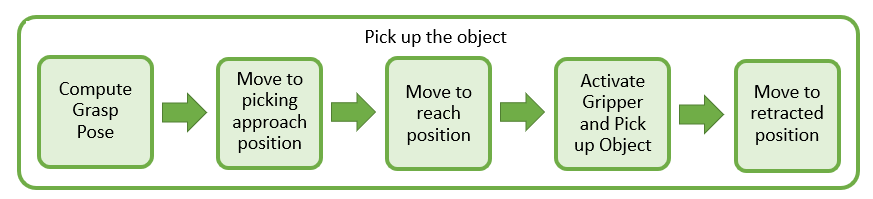

The exampleCommand`ComputeGraspPose` function computes the grasp pose. The class computes a task-space grasping position for each part. Intermediate steps for approaching and reaching towards the part are also defined relative to the object.

This robot picks up objects using a simulated pneumatic gripper. When the gripper is activated, exampleCommand`ActivateGripper` adds the collision mesh for the part onto the `rigidBodyTree` representation of the robot, which simulates grabbing it. Collision detection includes this object while it is attached. Then, the robot moves to a retracted position away from the other parts.

#### Place the Object

The robot then places the object on the appropriate shelf.

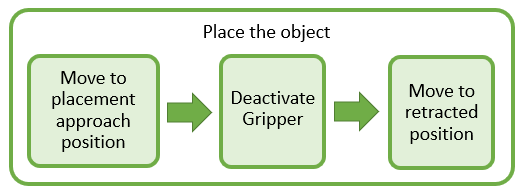

As with the picking workflow, the placement approach and retracted positions are computed relative to the known desired placement position. The gripper is deactivated using exampleCommand`ActivateGripper`, which removes the part from the robot.

### Moving the Manipulator to a Specified Pose

Most of the task execution consists of instructing the robot to move between different specified poses. The `exampleHelperPlanExecuteTrajectoryPickPlace` function defines a solver using a nonlinear model predictive controller (see [Nonlinear MPC](docid:mpc_ug.mw_4f117865-bf14-4e23-bedf-eee9732637c2)) that computes a feasible, collision-free optimized reference trajectory using [`nlmpcmove`](docid:mpc_ref.mw_953dc5ee-1b69-4a61-92d3-b6ae8a304f74) and [checkCollision](docid:robotics_ref.mw_2d888164-6615-4db2-8fac-df28e484c0ab)**. **Collision-checking is computed for the manipulator and environment using methods similar to [Check for Environmental Collisions with Manipulators](docid:robotics_examples.mw_9363e560-0c49-48ec-bdb5-f427241ca343). The obstacles are represented as spheres to ensure the accurate approximation of the contraint Jacobian in the definiton of the nonlinear model predictive control algorithm (see [1]). The helper function then simulates the motion of the manipulator under computed-torque control as it tracks the reference trajectory using the [`jointSpaceMotionModel`](docid:robotics_ref.mw_d82cc727-9467-4934-870a-2b0ca4917f2b) object, and updates the visualization. The helper function is called from the Stateflow chart via exampleCommand`MoveToTaskConfig`, which defines the correct inputs.

This workflow is examined in detail in [Plan and Execute Collision-Free Trajectories Using a KINOVA Gen3 Manipulator](docid:robotics_examples.mw_8454573b-3123-45c5-9ae1-6774f66b40a6). The controller is used to ensure collision-free motion. For simpler trajectories where the paths are known to be obstacle-free, trajectories could be executed using trajectory generation tools and simulated using the manipulator motion models. See [Plan and Execute Task- and Joint-Space Trajectories Using a KINOVA Gen3 Manipulator](docid:robotics_examples.mw_20e8553c-fc75-4688-8696-bac1b2693fa8).

## Task Scheduling in a Stateflow Chart 

This example uses a Stateflow chart to direct the workflow in MATLAB®. For more info on creating state flow starts, see [Create Stateflow Charts for Execution as MATLAB Objects](docid:stateflow_ug.mw_d580cbaa-5437-4e23-a9b5-d7fd4fc42ff7).

The Stateflow chart directs task execution in MATLAB by using command functions. When the command finishes executing, it sends an *input event* to wake up the chart and proceed to the next step of the task execution, see [Execute a Standalone Chart](docid:stateflow_ug.mw_99f798b7-fa0a-43ed-b2bc-c49d5e2801c3).

## Run and Visualize the Simulation

This simulation uses a KINOVA Gen3 manipulator with a Robotiq gripper. 

load('exampleHelperKINOVAGen3RobotiqGripper.mat'); 

### Initialize the Pick and Place coordinator

Set the initial robot configuration. Create the coordinator by giving the robot model, initial configuration, and end-effector name.

currentRobotJConfig = homeConfiguration(robot);
coordinator = exampleHelperCoordinatorPickPlace(robot,currentRobotJConfig, "gripper");

Specify pick-and-place properties.

%go to home configuration
coordinator.HomeRobotTaskConfig = trvec2tform([0.4, 0, 0.6])*axang2tform([0 1 0 pi]);
%hold over white beaker to pour
coordinator.HoldConfig = trvec2tform([[0.4 0.15 0.50]])*axang2tform([0 1 0 pi]);
%place blue beaker back on table
coordinator.PlacingPose{1} = trvec2tform([[-0.05, 0.45, 0.32]])*axang2tform([0 1 0 pi]);
%place red beaker back on table
coordinator.PlacingPose{2} = trvec2tform([[-0.25, 0.45, 0.32]])*axang2tform([0 1 0 pi]);
%place white beaker on mixing platform shelf
coordinator.PlacingPose{3} = trvec2tform([[0.3 0.5 0.345]])*axang2tform([0 1 0 pi]);
%place white beaker back in center table area
%coordinator.PlacingPose{4} = trvec2tform([[0.4 0.15 0.32]])*axang2tform([0 1 0 pi]);

### Run and Visualize the Simulation

Connect the Coordinator to the Stateflow Chart. Once started, the Stateflow chart is responsible for continuously going through the states of detecting objects, picking them up and placing them in the correct staging area. 

coordinator.FlowChart = exampleHelperFlowChartPickPlace('coordinator', coordinator); 

Use a dialog to start the pick-and-place task execution. 

answer = questdlg('Do you want to start mixing the solution?', ...
         'Start job','Yes','No', 'No');

switch answer
    case 'Yes'
        % Trigger event to start Pick and Place in the Stateflow Chart
        coordinator.FlowChart.startPickPlace;        
    case 'No'
        % End Pick and Place
        coordinator.FlowChart.endPickPlace;        
        delete(coordinator.FlowChart);
        delete(coordinator);
end

#### Ending the pick-and-place task

The Stateflow chart will finish executing automatically after 3 failed attempts to detect new objects. To end the pick-and-place task prematurely, uncomment and execute the following lines of code or press Ctrl+C in the command window. 

% coordinator.FlowChart.endPickPlace;        
% delete(coordinator.FlowChart);
% delete(coordinator);

### Observe the Simulation States

During execution, the active states at each point in time are highlighted in blue in the Stateflow chart. This helps keeping track of what the robot does and when. You can click through the subsystems to see the details of the state in action.

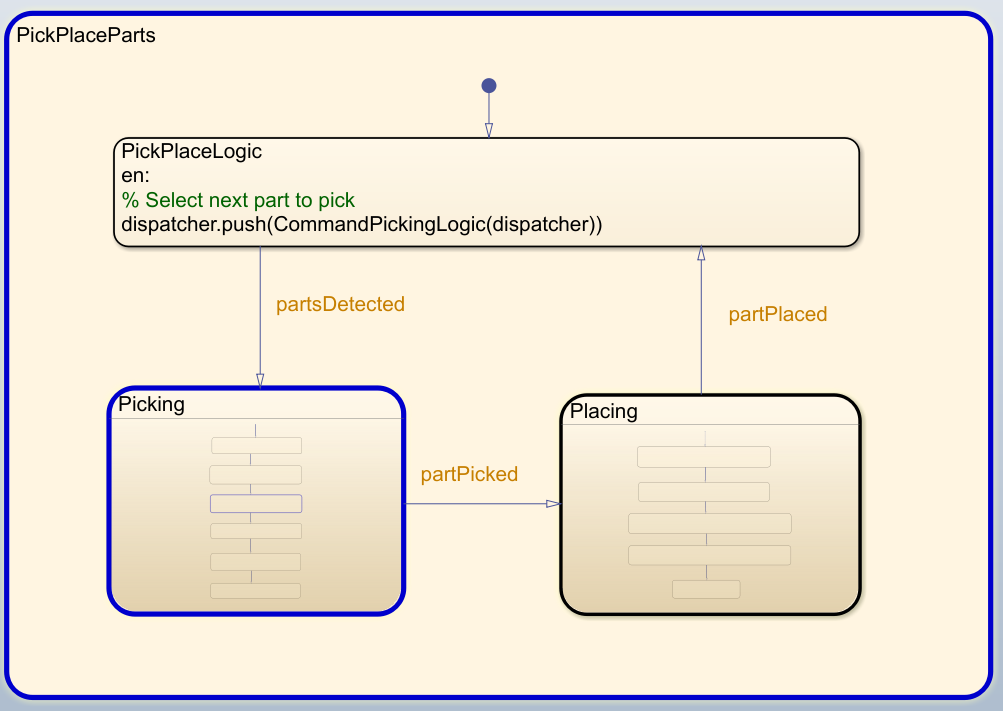

### Visualize the Pick-and-Place Action

The example uses `interactiveRigidBodyTree++` for robot visualization. The visualization shows the robot in the working area as it moves parts around. The robot avoids obstacles in the environment (blue cylinder) and places objects on top or bottom shelf based on their classification. The robot continues working until all parts have been placed.

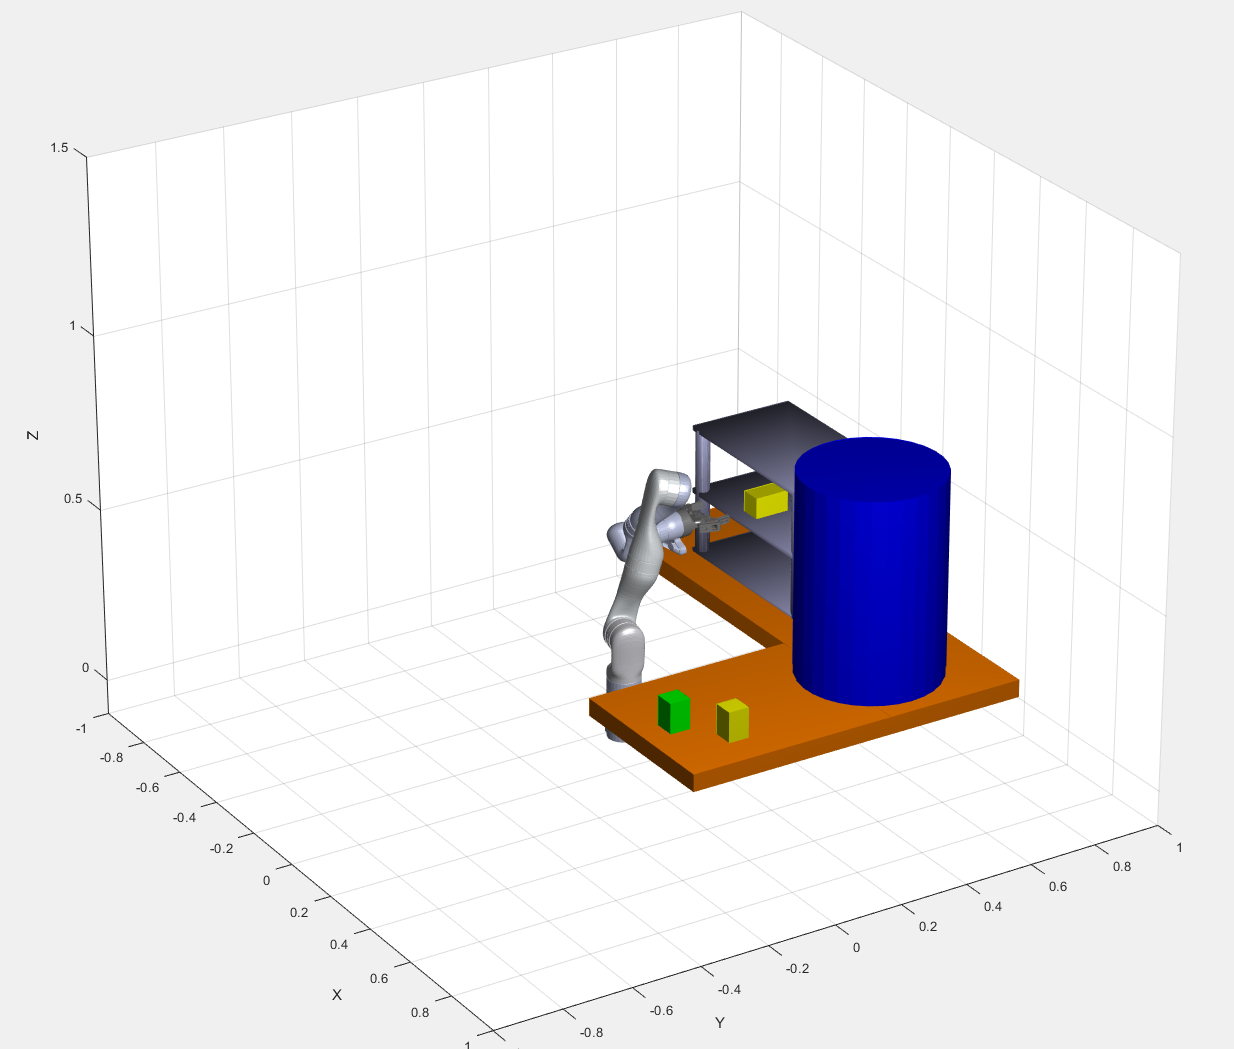

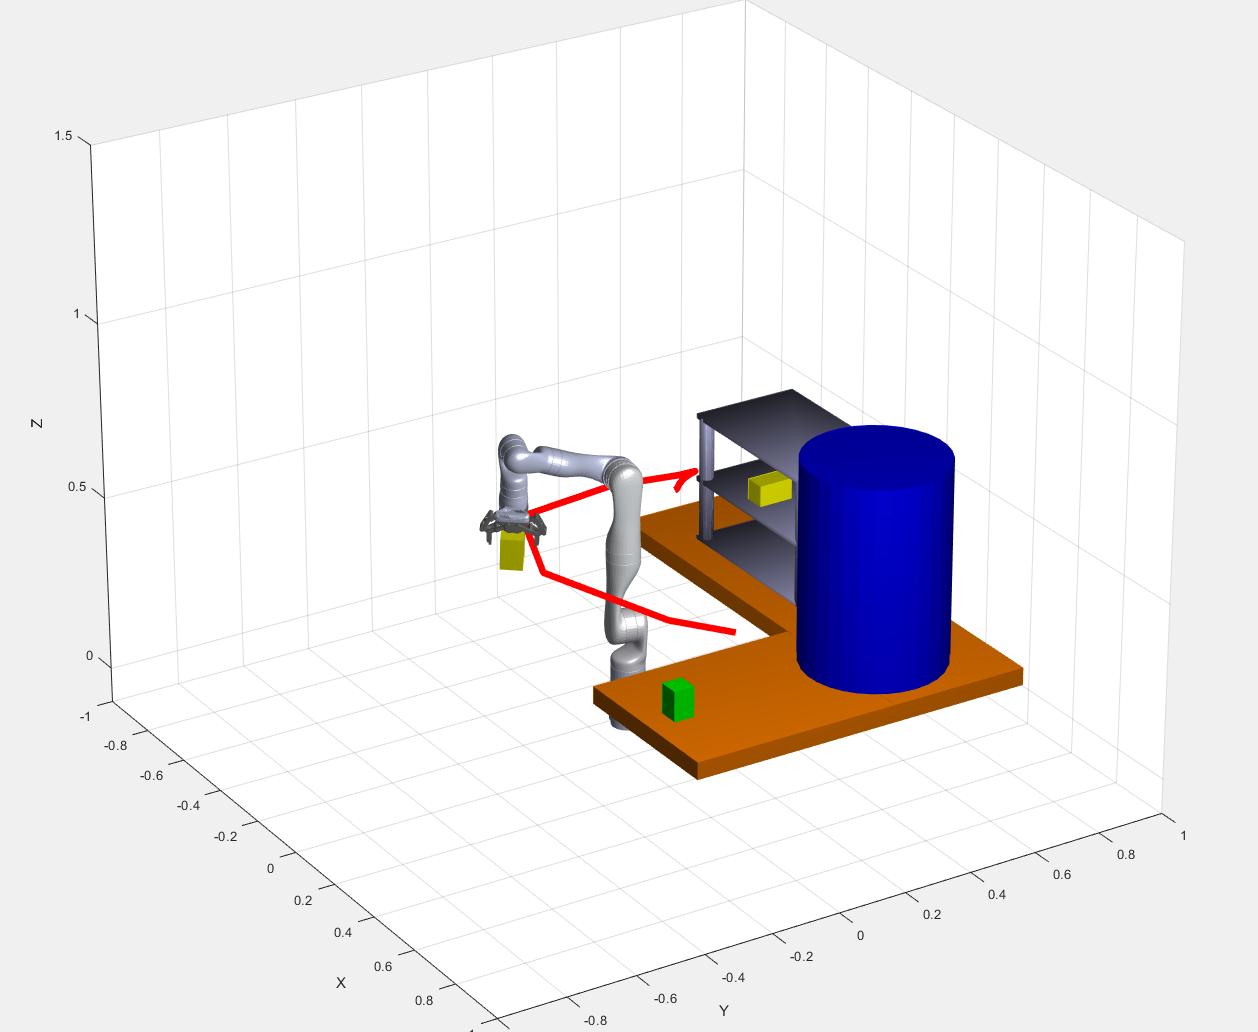

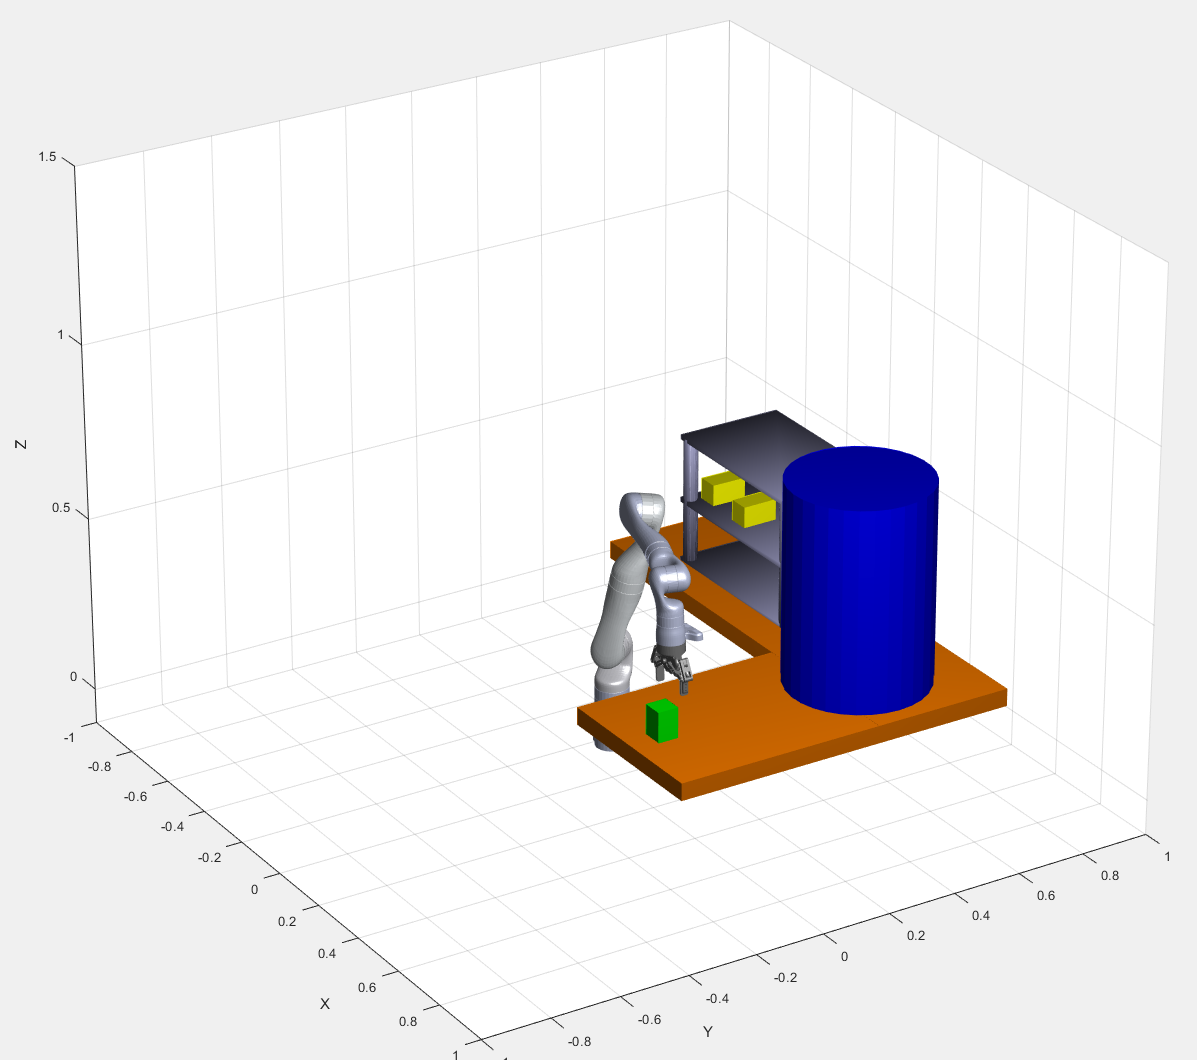

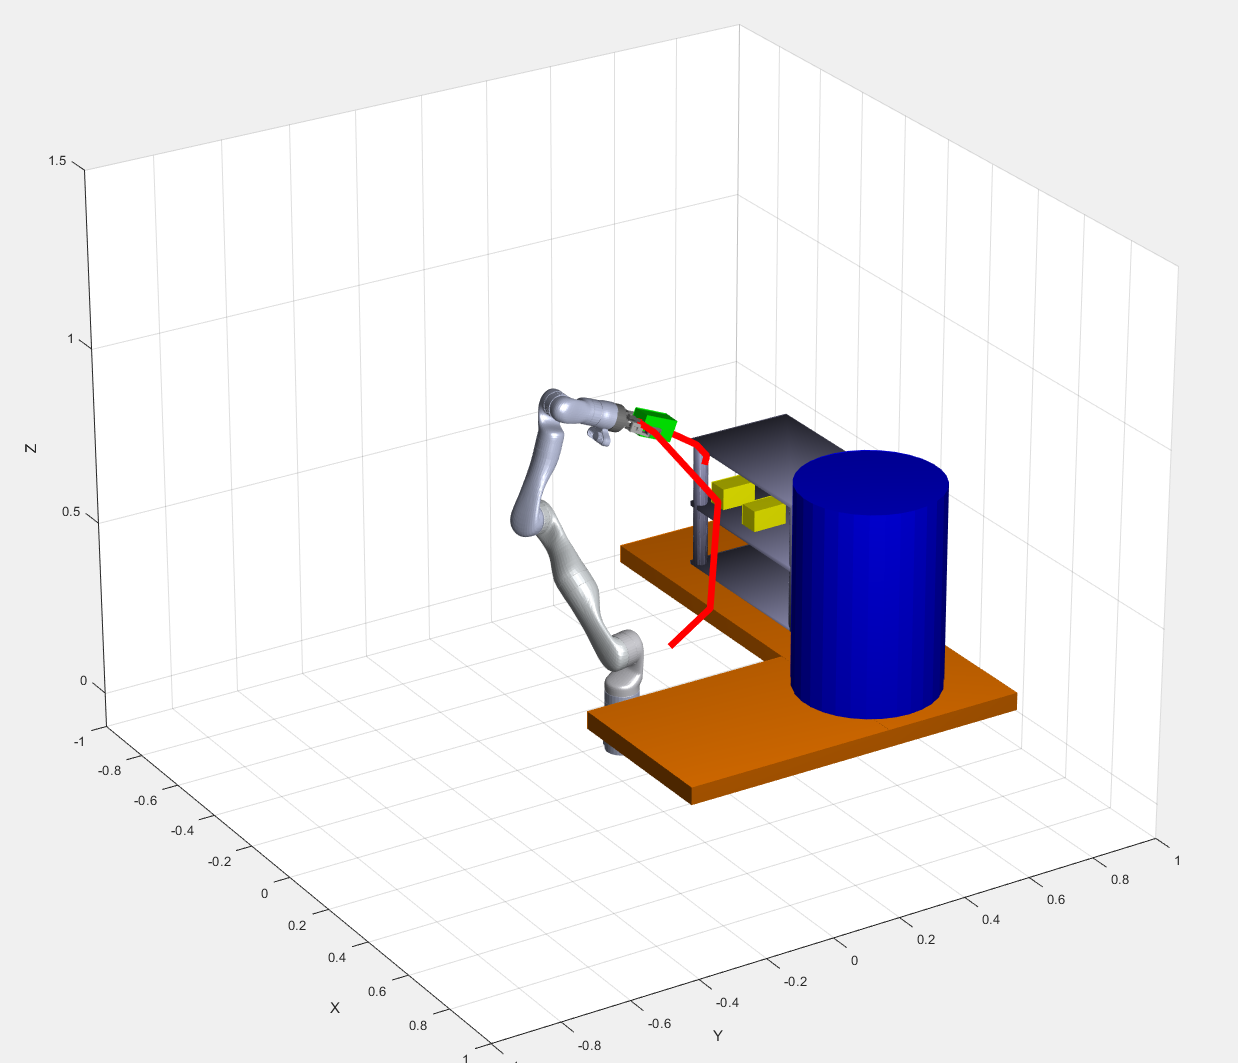

### References

[1] Schulman, J., et al. "Motion planning with sequential convex optimization and convex collision checking." *The International Journal of Robotics Research* 33.9 (2014): 1251-1270.

Copyright 2020 The MathWorks, Inc.